clear;
clc;

A

A = eye(8);
A(1,4) = 1;
A(2,5) = 1;
A(3,6) = 1;
A(4,7) = 9.81;
A(5,8) = 9.81;

disp(A)

    1.0000         0         0    1.0000         0         0         0         0
         0    1.0000         0         0    1.0000         0         0         0
         0         0    1.0000         0         0    1.0000         0         0
         0         0         0    1.0000         0         0    9.8100         0
         0         0         0         0    1.0000         0         0    9.8100
         0         0         0         0         0    1.0000         0         0
         0         0         0         0         0         0    1.0000         0
         0         0         0         0         0         0         0    1.0000



B

B = zeros(8,3);
B(6,1) = 1;
B(7,2) = 1;
B(8,3) = 1;
disp(B)

     0     0     0
     0     0     0
     0     0     0
     0     0     0
     0     0     0
     1     0     0
     0     1     0
     0     0     1



Q

Q = diag([100, 100, 100, 10, 10, 10, 1, 1]);
disp(Q)

   100     0     0     0     0     0     0     0
     0   100     0     0     0     0     0     0
     0     0   100     0     0     0     0     0
     0     0     0    10     0     0     0     0
     0     0     0     0    10     0     0     0
     0     0     0     0     0    10     0     0
     0     0     0     0     0     0     1     0
     0     0     0     0     0     0     0     1



R

R = eye(3)*0.1;
disp(R)

    0.1000         0         0
         0    0.1000         0
         0         0    0.1000



P

[P,K,L] = idare(A,B,Q,R,[],[])

P = 	1.0e+04 *

    0.0309    0.0000   -0.0000    0.0318    0.0000   -0.0000    0.1071    0.0000
    0.0000    0.0309   -0.0000    0.0000    0.0318   -0.0000    0.0000    0.1071
   -0.0000   -0.0000    0.0209   -0.0000   -0.0000    0.0109   -0.0000   -0.0000
    0.0318    0.0000   -0.0000    0.0557    0.0000   -0.0000    0.2241    0.0000
    0.0000    0.0318   -0.0000    0.0000    0.0557   -0.0000    0.0000    0.2241
   -0.0000   -0.0000    0.0109   -0.0000   -0.0000    0.0120   -0.0000   -0.0000
    0.1071    0.0000   -0.0000    0.2241    0.0000   -0.0000    1.1475   -0.0000
    0.0000    0.1071   -0.0000    0.0000    0.2241   -0.0000   -0.0000    1.1475


K =    -0.0000   -0.0000    0.9140   -0.0000   -0.0000    1.9132   -0.0000   -0.0000
    0.0934    0.0000   -0.0000    0.2886    0.0000   -0.0000    2.9157   -0.0000
    0.0000    0.0934    0.0000    0.0000    0.2886    0.0000    0.0000    2.9157


L =    0.0839 + 0.0000i
   0.0839 + 0.0000i
   0.0758 + 0.0000i
   0.0110 + 0.0000i
   0.0002 + 0.0102i
   0.0002 - 0.0102i
   0.0002 + 0.0102i
   0.0002 - 0.0102i


disp(round(P))

         309           0           0         318           0           0        1071           0
           0         309           0           0         318           0           0        1071
           0           0         209           0           0         109           0           0
         318           0           0         557           0           0        2241           0
           0         318           0           0         557           0           0        2241
           0           0         109           0           0         120           0           0
        1071           0           0        2241           0           0       11475           0
           0        1071           0           0        2241           0           0       11475



M = csvread('No.csv'); %N.csv
M2 = csvread('No2.csv'); %LQR.scv

quad_obs = M(:,1:9)

quad_obs =    -1.0000         0    0.0033    0.0000    0.0600    0.0000         0         0    0.3287
   -0.9997   -0.0000    0.0128    0.0000    0.1199    0.0000    0.0295   -0.0000    0.6232
   -0.9986   -0.0000    0.0279    0.0000    0.1799    0.0000    0.0843   -0.0000    0.8823
   -0.9961   -0.0000    0.0477    0.0000    0.2398    0.0000    0.1606   -0.0000    1.1053
   -0.9920   -0.0000    0.0717   -0.0000    0.2996    0.0000    0.2543   -0.0000    1.2925
   -0.9858   -0.0000    0.0991   -0.0000    0.3595    0.0000    0.3620   -0.0000    1.4449
   -0.9774   -0.0000    0.1292   -0.0000    0.4193   -0.0000    0.4804   -0.0000    1.5639
   -0.9665   -0.0000    0.1613   -0.0000    0.4609   -0.0000    0.6067    0.0000    1.6510
   -0.9531   -0.0000    0.1949   -0.0000    0.4859   -0.0000    0.7338    0.0000    1.7107
   -0.9372   -0.0000    0.2295   -0.0000    0.5009   -0.0000    0.8564    0.0000    1.7468


quad_act = M(:,10:13)

quad_act =    26.2435    0.0000    3.0000         0
   24.5830    0.0000    3.0000         0
   22.9267   -0.0000    3.0000         0
   21.3040   -0.0000    3.0000         0
   19.7373   -0.0000    3.0000         0
   18.2430   -0.0000    3.0000         0
   16.8323   -0.0000    3.0000         0
   15.5121   -0.0000    2.0858         0
   14.2848   -0.0000    1.2542         0
   13.1314   -0.0000    0.7542         0


pend_obs = M(:,14:22)

pend_obs =          0         0   -0.4020         0         0         0         0         0   -4.8038
         0         0   -0.3078         0         0         0         0         0   -4.6076
         0         0   -0.2177         0         0         0         0         0   -4.4114
         0         0   -0.1314         0         0         0         0         0   -4.2152
         0         0   -0.0491         0         0         0         0         0   -4.0190
         0         0    0.0294         0         0         0         0         0   -3.8228
         0         0    0.1039         0         0         0         0         0   -3.6266
         0         0    0.1744         0         0         0         0         0   -3.4304
         0         0    0.2411         0         0         0         0         0   -3.2342
         0         0    0.3038         0         0         0         0         0   -3.0380


quad_s0 = M(:,23:30)

quad_s0 =    -1.0000         0    0.5000         0         0   -5.0000         0         0
   -1.0000         0    0.4052         0         0   -4.4751    0.0000    0.0600
   -0.9997   -0.0000    0.3207    0.0295   -0.0000   -3.9844    0.0000    0.1199
   -0.9986   -0.0000    0.2455    0.0843   -0.0000   -3.5291    0.0000    0.1799
   -0.9961   -0.0000    0.1791    0.1606   -0.0000   -3.1099    0.0000    0.2398
   -0.9920   -0.0000    0.1208    0.2543   -0.0000   -2.7265   -0.0000    0.2996
   -0.9858   -0.0000    0.0697    0.3620   -0.0000   -2.3779   -0.0000    0.3595
   -0.9774   -0.0000    0.0253    0.4804   -0.0000   -2.0627   -0.0000    0.4193
   -0.9665   -0.0000   -0.0131    0.6067    0.0000   -1.7794   -0.0000    0.4609
   -0.9531   -0.0000   -0.0461    0.7338    0.0000   -1.5235   -0.0000    0.4859


t = M(:,31)

t =     0.0370
    0.2770
    0.4470
    0.6270
    0.8010
    0.9750
    1.1430
    1.3150
    1.4900
    1.6520


cost = M(:,32)

cost = 	1.0e+03 *

    1.1024
    1.0301
    0.9549
    0.8765
    0.7979
    0.7230
    0.6502
    0.5838
    0.5231
    0.4683


% stage_cost = M(:,33)
% terminal_cost = M(:,34)

quad_obs_2 = M2(:,1:9)

quad_obs_2 =    -1.0000         0    0.0033   -0.0000    0.4430   -0.0000         0         0    0.3326
   -0.9979    0.0000    0.0125   -0.0000    0.7633   -0.0000    0.2120    0.0000    0.5833
   -0.9904    0.0000    0.0256   -0.0000    0.9633   -0.0000    0.5357    0.0000    0.7254
   -0.9760    0.0000    0.0407    0.0000    1.0557   -0.0000    0.9091    0.0000    0.7888
   -0.9539    0.0000    0.0567    0.0000    1.0577   -0.0000    1.3013   -0.0000    0.8146
   -0.9239    0.0000    0.0733    0.0000    0.9862   -0.0000    1.6935   -0.0000    0.8394
   -0.8863   -0.0000    0.0906    0.0000    0.8571   -0.0000    2.0665   -0.0000    0.8901
   -0.8417   -0.0000    0.1093    0.0000    0.6854   -0.0000    2.3977   -0.0000    0.9806
   -0.7910   -0.0000    0.1302    0.0000    0.4861   -0.0000    2.6634   -0.0000    1.1094
   -0.7359   -0.0000    0.1539    0.0000    0.2747   -0.0000    2.8467   -0.0000    1.2600


quad_act_2 = M2(:,10:13)

quad_act_2 =    26.4423   -0.0000   22.5181         0
   24.7288    0.0000   16.5610         0
   23.4087    0.0000   10.4151         0
   22.7407    0.0000    4.8250         0
   22.5374    0.0000    0.1038         0
   22.5054    0.0000   -3.7328         0
   22.3672    0.0000   -6.7576         0
   21.9038    0.0000   -9.0180         0
   20.9878    0.0000  -10.5098         0
   19.6123    0.0000  -11.2131         0


pend_obs_2 = M2(:,14:22)

pend_obs_2 =          0         0   -0.4020         0         0         0         0         0   -4.8038
         0         0   -0.3078         0         0         0         0         0   -4.6076
         0         0   -0.2177         0         0         0         0         0   -4.4114
         0         0   -0.1314         0         0         0         0         0   -4.2152
         0         0   -0.0491         0         0         0         0         0   -4.0190
         0         0    0.0294         0         0         0         0         0   -3.8228
         0         0    0.1039         0         0         0         0         0   -3.6266
         0         0    0.1744         0         0         0         0         0   -3.4304
         0         0    0.2411         0         0         0         0         0   -3.2342
         0         0    0.3038         0         0         0         0         0   -3.0380


quad_s0_2 = M2(:,23:30)

quad_s0_2 =    -1.0000         0    0.5000         0         0   -5.0000         0         0
   -1.0000         0    0.4053         0         0   -4.4712   -0.0000    0.4430
   -0.9979    0.0000    0.3203    0.2120    0.0000   -4.0243   -0.0000    0.7633
   -0.9904    0.0000    0.2432    0.5357    0.0000   -3.6860   -0.0000    0.9633
   -0.9760    0.0000    0.1721    0.9091    0.0000   -3.4264    0.0000    1.0557
   -0.9539    0.0000    0.1058    1.3013   -0.0000   -3.2044    0.0000    1.0577
   -0.9239    0.0000    0.0439    1.6935   -0.0000   -2.9834    0.0000    0.9862
   -0.8863   -0.0000   -0.0133    2.0665   -0.0000   -2.7365    0.0000    0.8571
   -0.8417   -0.0000   -0.0651    2.3977   -0.0000   -2.4498    0.0000    0.6854
   -0.7910   -0.0000   -0.1109    2.6634   -0.0000   -2.1248    0.0000    0.4861


t_2 = M2(:,31)

t_2 =     0.0050
    0.3870
    0.5340
    0.6880
    0.8280
    0.9700
    1.1120
    1.2640
    1.4070
    1.5440


cost_2 = M2(:,32)

cost_2 = 	1.0e+05 *

    0.2419
    0.1685
    0.1031
    0.0577
    0.0319
    0.0210
    0.0198
    0.0243
    0.0308
    0.0361


T = 1.5

T = 1.5000

t2 = linspace(0,T,size(quad_obs,1))

t2 =          0    0.0200    0.0400    0.0600    0.0800    0.1000    0.1200    0.1400    0.1600    0.1800    0.2000    0.2200    0.2400    0.2600    0.2800    0.3000    0.3200    0.3400    0.3600    0.3800    0.4000    0.4200    0.4400    0.4600    0.4800    0.5000    0.5200    0.5400    0.5600    0.5800    0.6000    0.6200    0.6400    0.6600    0.6800    0.7000    0.7200    0.7400    0.7600    0.7800    0.8000    0.8200    0.8400    0.8600    0.8800    0.9000    0.9200    0.9400    0.9600    0.9800


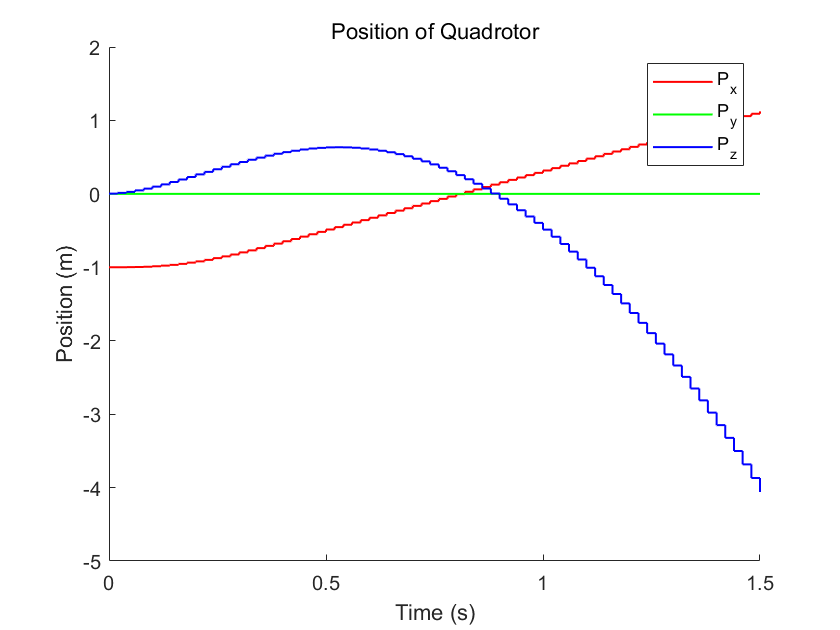

l_w = 1;
m_s = 20;

figure()
hold on
stairs(t2,quad_obs(:,1),'r',"LineWidth",l_w)
stairs(t2,quad_obs(:,2),'g',"LineWidth",l_w)
stairs(t2,quad_obs(:,3),'b',"LineWidth",l_w)
hold off
title('Position of Quadrotor')
xlabel('Time (s)')
ylabel('Position (m)')
legend('P_x','P_y','P_z')

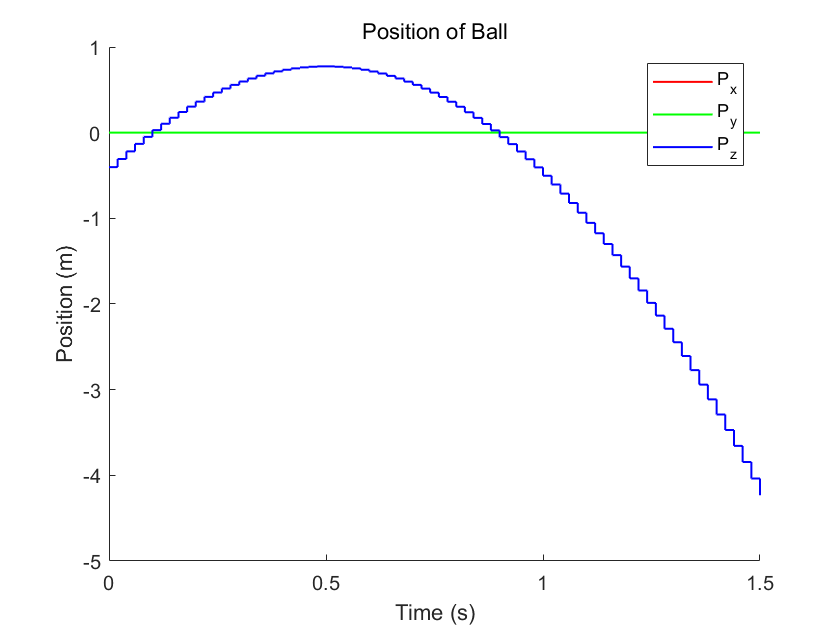


figure()
hold on
stairs(t2,pend_obs(:,1),'r',"LineWidth",l_w)
stairs(t2,pend_obs(:,2),'g',"LineWidth",l_w)
stairs(t2,pend_obs(:,3),'b',"LineWidth",l_w)
hold off
title('Position of Ball')
xlabel('Time (s)')
ylabel('Position (m)')
legend('P_x','P_y','P_z')

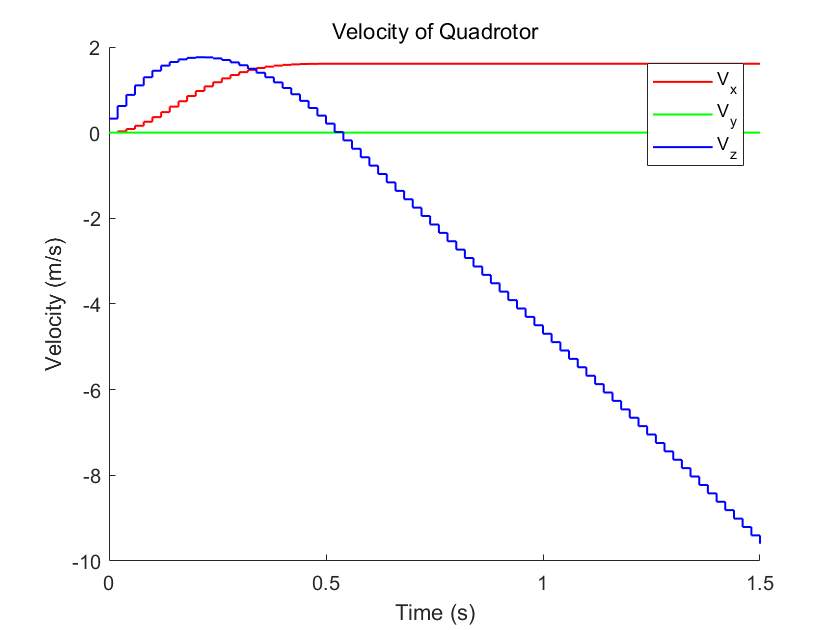

figure()
hold on
stairs(t2,quad_obs(:,7),'r',"LineWidth",l_w)
stairs(t2,quad_obs(:,8),'g',"LineWidth",l_w)
stairs(t2,quad_obs(:,9),'b',"LineWidth",l_w)
hold off
title('Velocity of Quadrotor')
xlabel('Time (s)')
ylabel('Velocity (m/s)')
legend('V_x','V_y','V_z')

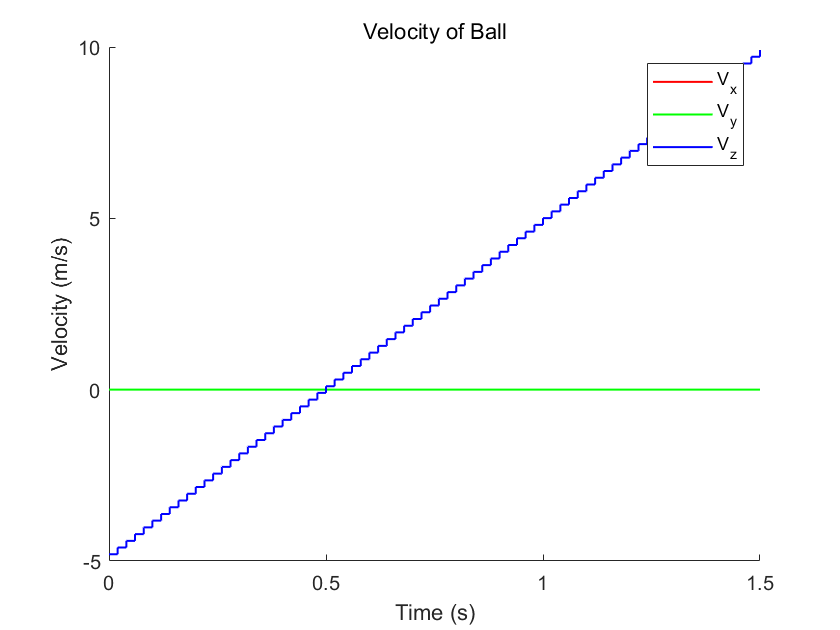


figure()
hold on
stairs(t2,pend_obs(:,7),'r',"LineWidth",l_w)
stairs(t2,pend_obs(:,8),'g',"LineWidth",l_w)
stairs(t2,pend_obs(:,9),'b',"LineWidth",l_w)
hold off
title('Velocity of Ball')
xlabel('Time (s)')
ylabel('Velocity (m/s)')
legend('V_x','V_y','V_z')

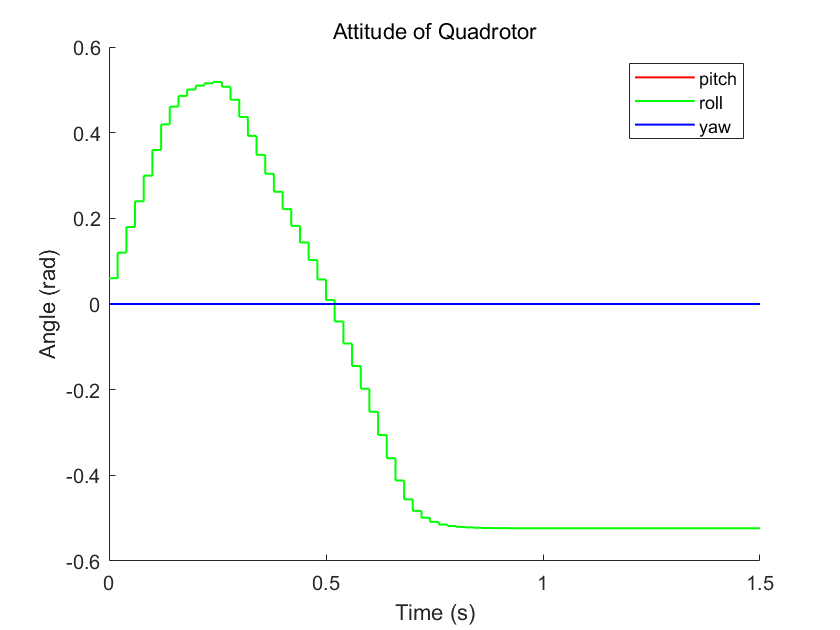

figure()
hold on
stairs(t2,quad_obs(:,4),'r',"LineWidth",l_w)
stairs(t2,quad_obs(:,5),'g',"LineWidth",l_w)
stairs(t2,quad_obs(:,6),'b',"LineWidth",l_w)
hold off
title('Attitude of Quadrotor')
xlabel('Time (s)')
ylabel('Angle (rad)')
legend('pitch','roll','yaw')

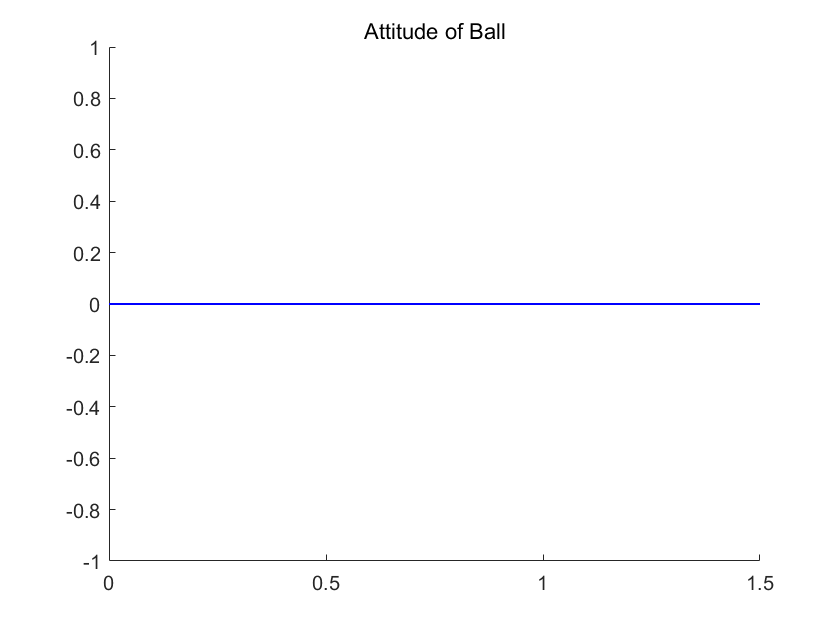


figure()
hold on
stairs(t2,pend_obs(:,4),'r',"LineWidth",l_w)
stairs(t2,pend_obs(:,5),'g',"LineWidth",l_w)
stairs(t2,pend_obs(:,6),'b',"LineWidth",l_w)
hold off
title('Attitude of Ball')

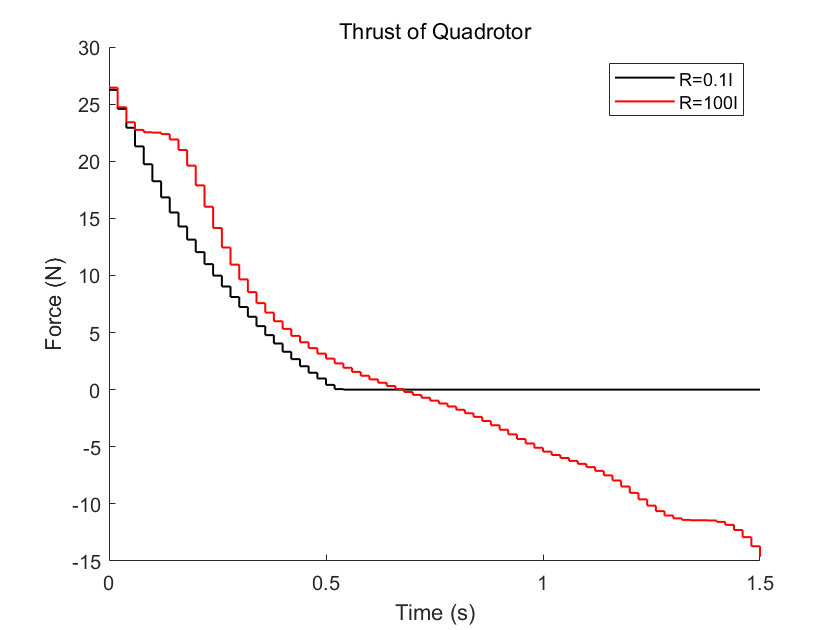

figure()
hold on
stairs(t2,quad_act(:,1),'k',"LineWidth",l_w)
stairs(t2,quad_act_2(:,1),'r',"LineWidth",l_w)
% stairs(t2,quad_act_3(:,1),'g',"LineWidth",l_w)
% stairs(t2,quad_act_4(:,1),'b',"LineWidth",l_w)
% stairs(t2,quad_act_5(:,1),'c',"LineWidth",l_w)
% stairs(t2,quad_act_6(:,1),'m',"LineWidth",l_w)
hold off
title('Thrust of Quadrotor')
xlabel('Time (s)')
ylabel('Force (N)')
legend('R=0.1I','R=100I','R=10I','R=1I','R=0.01I','R=0.001I')

% figure()
% hold on
% stairs(t2,quad_s0(:,1),'r',"LineWidth",l_w)
% stairs(t2,quad_s0(:,3),'b',"LineWidth",l_w)
% stairs(t2,quad_s0_2(:,1),'r',"LineWidth",l_w)
% stairs(t2,quad_s0_2(:,3),'b',"LineWidth",l_w)
% stairs(t2,quad_s0_3(:,1),'r',"LineWidth",l_w)
% stairs(t2,quad_s0_3(:,3),'b',"LineWidth",l_w)
% stairs(t2,quad_s0_4(:,1),'r',"LineWidth",l_w)
% stairs(t2,quad_s0_4(:,3),'b',"LineWidth",l_w)
% hold off
% title('Relative Position of Quadrotor')
% xlabel('Time (s)')
% ylabel('Position (m)')
% legend('P_x','P_y','P_z')
% 
% figure()
% subplot(211)
% hold on
% stairs(t2,quad_s0(:,3),'k',"LineWidth",l_w)
% stairs(t2,quad_s0_2(:,3),'r',"LineWidth",l_w)
% stairs(t2,quad_s0_3(:,3),'g',"LineWidth",l_w)
% stairs(t2,quad_s0_4(:,3),'b',"LineWidth",l_w)
% stairs(t2,quad_s0_5(:,3),'c',"LineWidth",l_w)
% stairs(t2,quad_s0_6(:,3),'m',"LineWidth",l_w)
% a_idx = abs(quad_s0(:,3))<=0.05;
% a = t2(a_idx);
% xline(a(1),'k',"LineWidth",l_w)
% %scatter(t2(a_idx),quad_s0(a_idx),m_s,'ko','filled','LineWidth',0.1)
% b = t2(abs(quad_s0_2(:,3))<=0.1)
% xline(b(1),'r',"LineWidth",l_w)
% c = t2(abs(quad_s0_3(:,3))<=0.1)
% xline(c(1),'g',"LineWidth",l_w)
% d = t2(abs(quad_s0_4(:,3))<=0.1)
% xline(d(1),'b',"LineWidth",l_w)
% e = t2(abs(quad_s0_5(:,3))<=0.1)
% xline(e(1),'c',"LineWidth",l_w)
% f = t2(abs(quad_s0_6(:,3))<=0.1)
% xline(f(1),'m',"LineWidth",l_w)
% title('Relative Position of Quadrotor')
% yline(0)
% ylabel('P_z (m)')
% hold off
% subplot(212)
% hold on
% stairs(t2,quad_s0(:,1),'k',"LineWidth",l_w)
% stairs(t2,quad_s0_2(:,1),'r',"LineWidth",l_w)
% stairs(t2,quad_s0_3(:,1),'g',"LineWidth",l_w)
% stairs(t2,quad_s0_4(:,1),'b',"LineWidth",l_w)
% stairs(t2,quad_s0_5(:,1),'c',"LineWidth",l_w)
% stairs(t2,quad_s0_6(:,1),'m',"LineWidth",l_w)
% xline(a(1),'k',"LineWidth",l_w)
% xline(b(1),'r',"LineWidth",l_w)
% xline(c(1),'g',"LineWidth",l_w)
% xline(d(1),'b',"LineWidth",l_w)
% xline(e(1),'c',"LineWidth",l_w)
% xline(f(1),'m',"LineWidth",l_w)
% yline(-0.05)
% yline(0.05)
% ylim([-0.5 0.5])
% scatter(t2(a_idx),quad_s0(a_idx),m_s,'ko','filled','LineWidth',0.1)
% scatter(t2(abs(quad_s0_5(:,3))<=0.05),quad_s0_5(abs(quad_s0_5(:,3))<=0.05),m_s,'co','filled','LineWidth',0.1)
% scatter(t2(abs(quad_s0_6(:,3))<=0.06),quad_s0_6(abs(quad_s0_6(:,3))<=0.06),m_s,'mo','filled','LineWidth',0.1)
% hold off
% xlabel('Time (s)')
% ylabel('P_x (m)')
% legend('R=0.1I','R=100I','R=10I','R=1I','R=0.01I','R=0.001I')

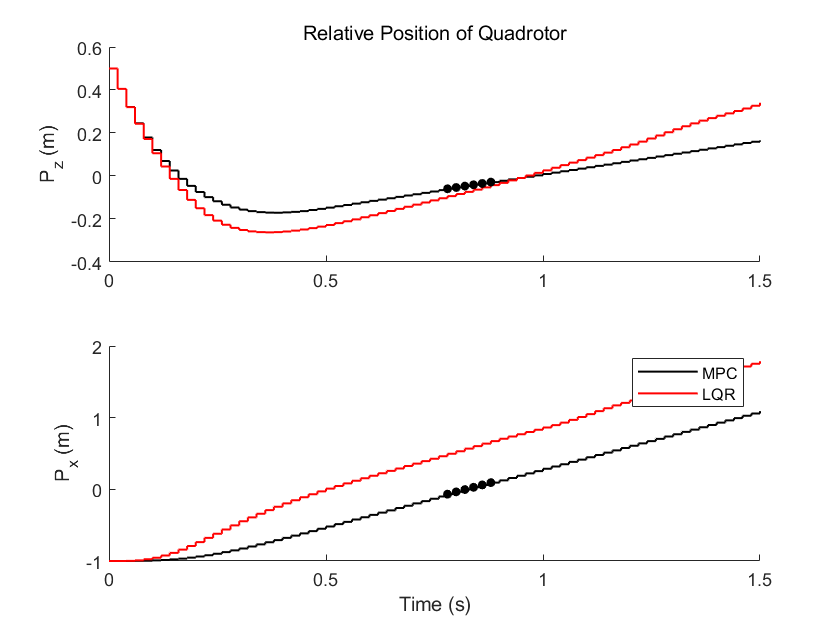

% Best
figure()
subplot(211)
hold on
stairs(t2,quad_s0(:,3),'k',"LineWidth",l_w)
stairs(t2,quad_s0_2(:,3),'r',"LineWidth",l_w)
% stairs(t2,quad_s0_3(:,3),'g',"LineWidth",l_w)
% stairs(t2,quad_s0_4(:,3),'b',"LineWidth",l_w)
% stairs(t2,quad_s0_5(:,3),'c',"LineWidth",l_w)
% stairs(t2,quad_s0_6(:,3),'m',"LineWidth",l_w)
a =  sqrt(sum(quad_s0(:,1:3).^2,2))<=0.1;
b = sqrt(sum(quad_s0_2(:,1:3).^2,2))<=0.1;
% c = sqrt(sum(quad_s0_3(:,1:3).^2,2))<=0.1;
% d = sqrt(sum(quad_s0_4(:,1:3).^2,2))<=0.1;
% e = sqrt(sum(quad_s0_5(:,1:3).^2,2))<=0.1;
% f = sqrt(sum(quad_s0_6(:,1:3).^2,2))<=0.1;
scatter(t2(a),quad_s0(a,3),m_s,'ko','filled','LineWidth',0.1)
scatter(t2(b),quad_s0_2(b,3),m_s,'ro','filled','LineWidth',0.1)
% scatter(t2(c),quad_s0_3(c,3),m_s,'go','filled','LineWidth',0.1)
% scatter(t2(d),quad_s0_4(d,3),m_s,'bo','filled','LineWidth',0.1)
% scatter(t2(e),quad_s0_5(e,3),m_s,'co','filled','LineWidth',0.1)
% scatter(t2(f),quad_s0_6(f,3),m_s,'mo','filled','LineWidth',0.1)
title('Relative Position of Quadrotor')
ylabel('P_z (m)')
hold off
subplot(212)
hold on
stairs(t2,quad_s0(:,1),'k',"LineWidth",l_w)
stairs(t2,quad_s0_2(:,1),'r',"LineWidth",l_w)
% stairs(t2,quad_s0_3(:,1),'g',"LineWidth",l_w)
% stairs(t2,quad_s0_4(:,1),'b',"LineWidth",l_w)
% stairs(t2,quad_s0_5(:,1),'c',"LineWidth",l_w)
% stairs(t2,quad_s0_6(:,1),'m',"LineWidth",l_w)
scatter(t2(a),quad_s0(a,1),m_s,'ko','filled','LineWidth',0.1)
scatter(t2(b),quad_s0_2(b,1),m_s,'ro','filled','LineWidth',0.1)
% scatter(t2(c),quad_s0_3(c,1),m_s,'go','filled','LineWidth',0.1)
% scatter(t2(d),quad_s0_4(d,1),m_s,'bo','filled','LineWidth',0.1)
% scatter(t2(e),quad_s0_5(e,1),m_s,'co','filled','LineWidth',0.1)
% scatter(t2(f),quad_s0_6(f,1),m_s,'mo','filled','LineWidth',0.1)
hold off
xlabel('Time (s)')
ylabel('P_x (m)')
legend('MPC','LQR')

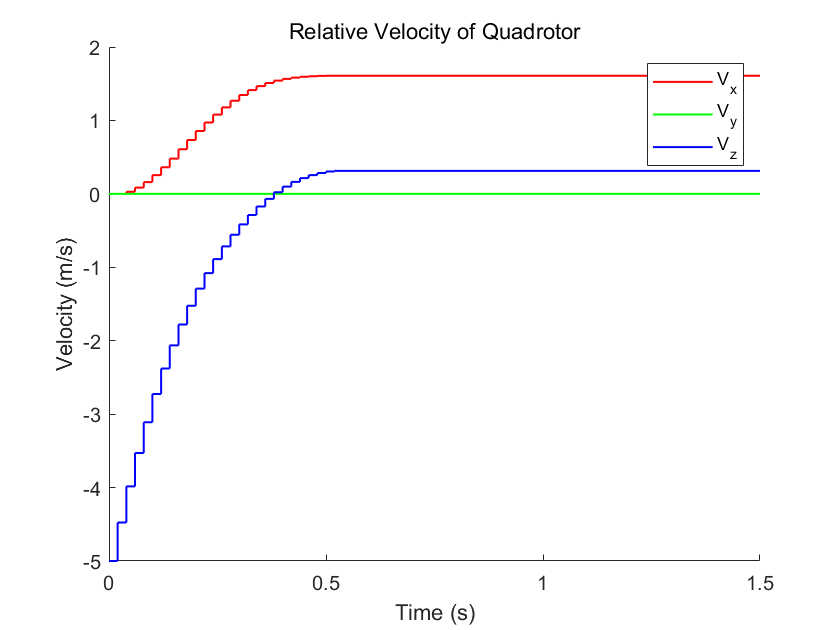

figure()
hold on
stairs(t2,quad_s0(:,4),'r',"LineWidth",l_w)
stairs(t2,quad_s0(:,5),'g',"LineWidth",l_w)
stairs(t2,quad_s0(:,6),'b',"LineWidth",l_w)
hold off
title('Relative Velocity of Quadrotor')
xlabel('Time (s)')
ylabel('Velocity (m/s)')
legend('V_x','V_y','V_z')

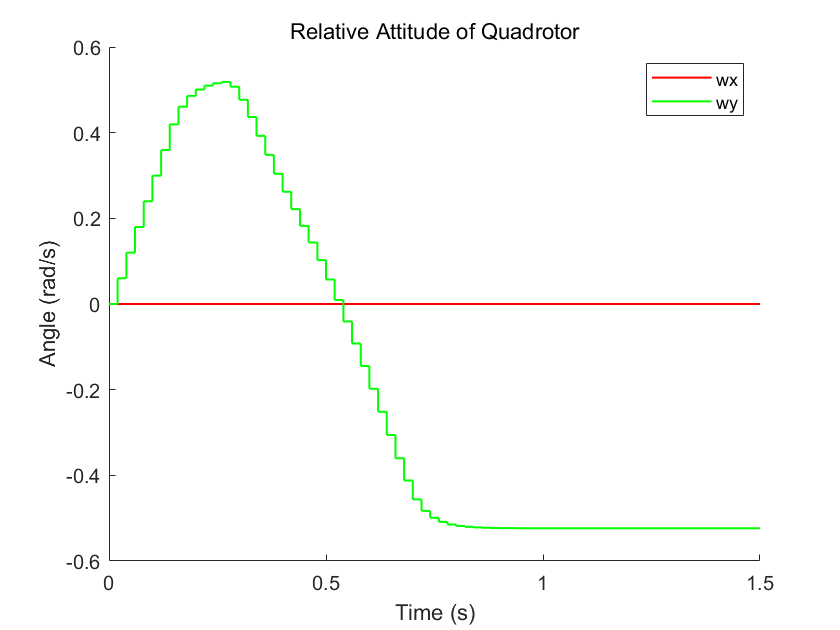


figure()
hold on
stairs(t2,quad_s0(:,7),'r',"LineWidth",l_w)
stairs(t2,quad_s0(:,8),'g',"LineWidth",l_w)
hold off
title('Relative Attitude of Quadrotor')
xlabel('Time (s)')
ylabel('Angle (rad/s)')
legend('wx','wy')

% a = terminal_cost(2:size(terminal_cost,1));
% b = terminal_cost(1:(size(terminal_cost,1)-1));
% terminal_cost_diff = a-b;

% figure()
% hold on
% stairs(t2,cost,'r',"LineWidth",l_w)
% hold off
% title('Cost')
% xlabel('Time (s)')
% ylabel('Cost')
% 
% figure()
% hold on
% stairs(t2,stage_cost,'g',"LineWidth",l_w)
% stairs(t2,terminal_cost,'b',"LineWidth",l_w)
% hold off
% title('Cost')
% xlabel('Time (s)')
% ylabel('Cost')
% legend('stage cost','terminal cost')
% 
% figure()
% hold on
% stairs(t2(2:size(terminal_cost,1)),-stage_cost(2:size(terminal_cost,1)),'g',"LineWidth",l_w)
% stairs(t2(2:size(terminal_cost,1)),terminal_cost_diff,'b',"LineWidth",l_w)
% hold off
% title('Cost')
% xlabel('Time (s)')
% ylabel('Cost')
% legend('-l(x,u)','V_f(f(x,u))-V_f(x)')